T = 0.03;
%delovna točka
U00 = 5.1;
Y00 = 5.3464;
t = 0:T:60;
simin_val = 5.1:0.25:6.1;
simin = simin_val';
% mrtva cona se konča pri 4.6
% gremo do cca 7
% najprej probat na 0.25V natančno

% vhodni signal
toWorkspace = 5;

% Y_all = [Y_46.Data,Y_485.Data,Y_51.Data,Y_535.Data,Y_56.Data,Y_585.Data,Y_61.Data,Y_635.Data,Y_66.Data,Y_685.Data];

Y_end = mean(Y_all(end-30:end,:),1);

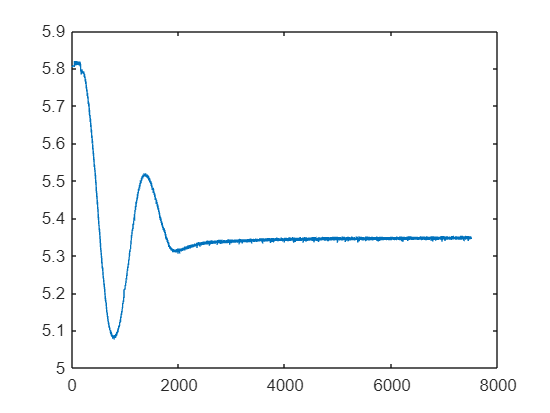

figure
plot(Y_all(:,3))

%plot(Y_56.Data)
U_PRBS = prbs(10) + 5.1;
U_PRBS_T = prbs(10) + 5.1;
U = ones(7500,1)*5.1;
U_T = ones(length(t)-length(U_PRBS_T),1)*5.1;

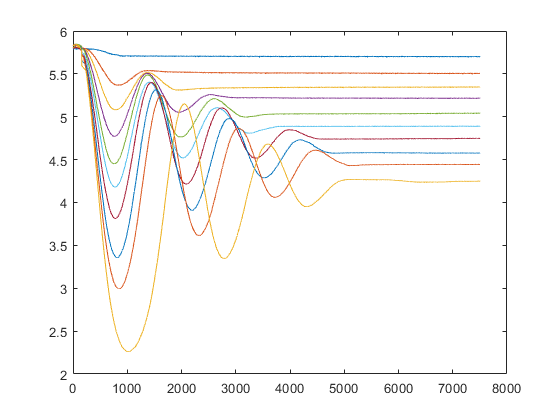

figure
%plot(U_PRBS)
plot(Y_all)

U_prbs = [U;U_PRBS];
U_prbs_T = [U_T;U_PRBS_T];
U_prbs_11 = [U;prbs(11)+5.1];
U_prbs_12 = [U;prbs(12)+5.1];
%plot(U_prbs)

PRBS_true = [t',U_prbs_T];


% plot(out.simout)
% exp_1 = [PRBS_true,out.simout.Data];


T = 0.03;
Len_U = length(U_T)*T - (20*0.03)

Len_U = 28.7400

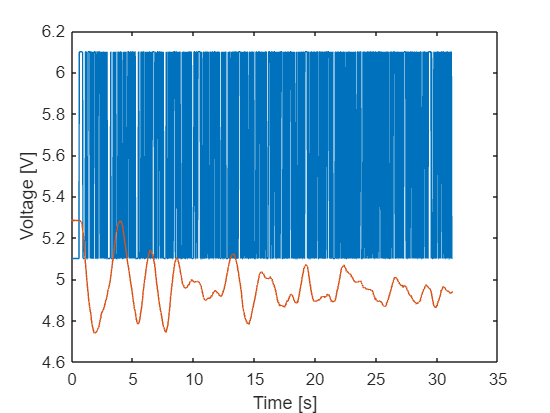

t2 = 0:T:(60-Len_U);
figure
plot(t2,exp_1((Len_U/0.03)+1:end,2))
xlabel("Time [s]")
ylabel("Voltage [V]")
hold on;
plot(t2,exp_1((Len_U/0.03)+1:end,3))
xlabel("Time [s]")
ylabel("Voltage [V]")

T = 0.15;
U00 = 5.1;
Y00 = 5.3464;
t = 0:T:90;
simin_val = 5.1:0.25:6.1;
simin = simin_val';
% vhodni signal
toWorkspace = 5;
U_PRBS_T = prbs(9) + 5.1;
U_T = ones(length(t)-length(U_PRBS_T),1)*5.1;
U_prbs_T = [U_T;U_PRBS_T];
% figure
% plot(t,U_prbs_T)
% xlabel("Time [s]")
% ylabel("Voltage [V]")
PRBS_true = [t',U_prbs_T];


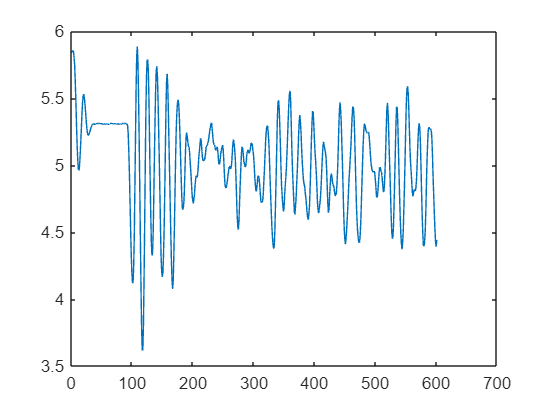

figure
plot(out.simout.Data)

final = [PRBS_true,out.simout.Data]

final =          0    5.1000    5.8435
    0.1500    5.1000    5.8441
    0.3000    5.1000    5.8557
    0.4500    5.1000    5.8484
    0.6000    5.1000    5.8047
    0.7500    5.1000    5.7458
    0.9000    5.1000    5.6201
    1.0500    5.1000    5.4800
    1.2000    5.1000    5.3091
    1.3500    5.1000    5.1593
